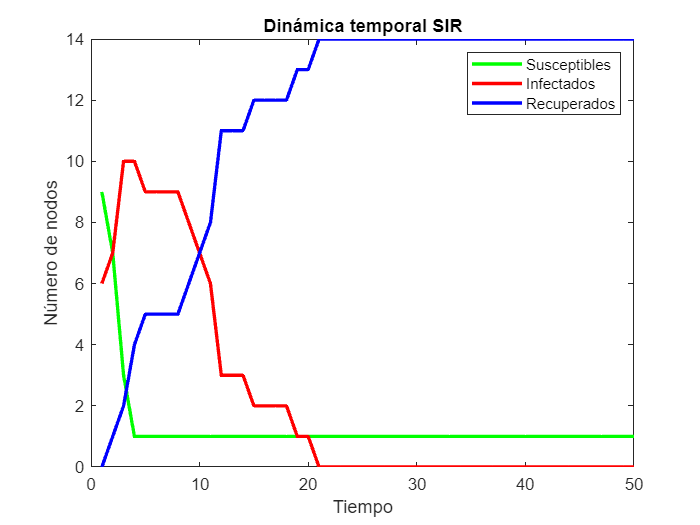

% Definir parámetros
beta = 0.5;
gamma = 0.1;
tiempo_recuperacion = 50;
seed = 1;

% Crear la matriz de adyacencia
matriz_adyacencia = zeros(15);

% Definir las aristas
aristas = [
    9 3; 3 14; 3 1; 1 8; 1 10; 8 10; 1 14; 14 11; 11 13; 13 7;
    10 5; 7 6; 14 12; 1 6; 1 11; 10 12; 12 6; 5 2; 6 2; 12 4; 12 3; 4 7
];

% Llenar la matriz de adyacencia con unos en las posiciones correspondientes
for i = 1:size(aristas, 1)
    matriz_adyacencia(aristas(i, 1), aristas(i, 2)) = 1;
    matriz_adyacencia(aristas(i, 2), aristas(i, 1)) = 1;
end

% Crear el grafo
G = graph(matriz_adyacencia);

% Número total de nodos
num_nodos = numnodes(G);

% Establecer la semilla para la reproducibilidad
rng(seed);

% Inicializar estado de los nodos
estado = zeros(1, num_nodos);
estado(1) = 1;  % Nodo inicial infectado

% Listas para almacenar datos de S, I, R en el tiempo
data_s = zeros(1, tiempo_recuperacion);
data_i = zeros(1, tiempo_recuperacion);
data_r = zeros(1, tiempo_recuperacion);

% Evolucionar la dinámica temporal
for paso = 1:tiempo_recuperacion
    nuevos_infectados = [];

    % Propagar la infección
    for nodo = find(estado == 1)
        % Propagar la infección a los vecinos susceptibles
        vecinos_susceptibles = neighbors(G, nodo);
        
        % Verificar si hay vecinos susceptibles
        vecinos_susceptibles = vecinos_susceptibles(estado(vecinos_susceptibles) == 0);

        % Verificar si la condición beta se cumple
        infectar = rand(1, length(vecinos_susceptibles)) < beta;
        
        % Agregar los nuevos infectados
        nuevos_infectados = [nuevos_infectados, vecinos_susceptibles(infectar)];
    end

    % Actualizar los estados de los nodos
    estado(nuevos_infectados) = 1;

    % Recuperación determinista
    nodos_infectados = find(estado == 1);
    recuperar = rand(1, length(nodos_infectados)) < gamma;
    
    % Actualizar el estado a recuperado
    estado(nodos_infectados(recuperar)) = 2;

    % Almacenar datos de S, I, R
    data_s(paso) = sum(estado == 0);
    data_i(paso) = sum(estado == 1);
    data_r(paso) = sum(estado == 2);
end
% Visualizar las series temporales
figure;
tiempo = 1:tiempo_recuperacion;
plot(tiempo, data_s, 'g', 'LineWidth', 2, 'DisplayName', 'Susceptibles');
hold on;
plot(tiempo, data_i, 'r', 'LineWidth', 2, 'DisplayName', 'Infectados');
plot(tiempo, data_r, 'b', 'LineWidth', 2, 'DisplayName', 'Recuperados');
xlabel('Tiempo');
ylabel('Número de nodos');
legend('show');
title('Dinámica temporal SIR');